# Actividad 2.1 (Parametrización de trayectorias)

A01798275 Bruno Manuel Zamora Garcia

clear all 
close all 
clc

#### 2. Implementar el código requerido para generar la parametrización de las siguientes trayectorias en un plano 2D.

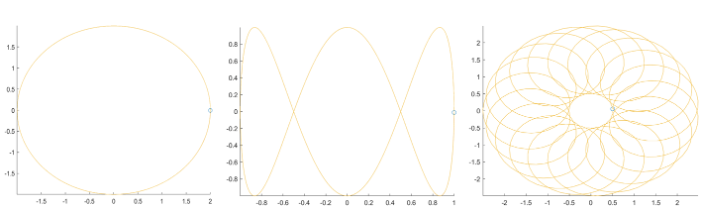

Primero necesitaba una curva básica para empezar, así que pensé en la circunferencia. Recordé que la forma paramétrica de un círculo es `x = cos(t)` y `y = sin(t)`, donde `t` es el ángulo en radianes. Como quería que la circunferencia fuera más grande, simplemente multipliqué por 2: `cos(t)*2` y `sin(t)*2`.

Luego, para generar los puntos, hice un vector `t` que va de 0 a 2π2, usando paso pequeño (0.001) para que la curva salga suave y sin picos.

 El resultado fue una circunferencia de radio 2, centrada en el origen, que se traza poco a poco con animación.

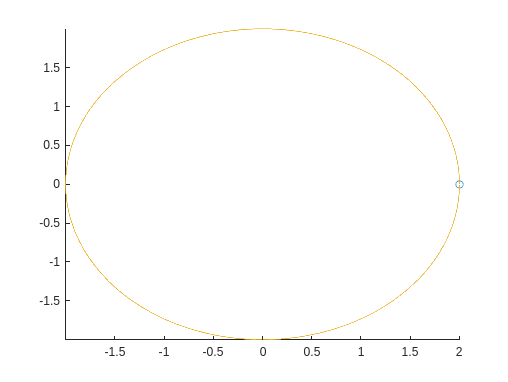

t = [0:0.001:2*pi];
x1 = cos(t)*2;
y1 = sin(t)*2;
comet(x1,y1)

En este caso quería ver qué pasaba si una de las funciones tenía mayor frecuencia. Dejé `x = cos(t)` igual, pero en `y` puse `sin(3*t)` para que se repita más veces.

Esto lo hice porque el número 3 dentro del seno hace que se repita 3 veces más rápido que un seno normal, así que en lugar de una sola vuelta, hay 3 oscilaciones en el eje y. Quería observar cómo cambia la forma de la curva al cambiar la frecuencia en un solo eje.

Usé el mismo rango de `t` que antes y lo mismo, con paso pequeño para que se vea bien. 

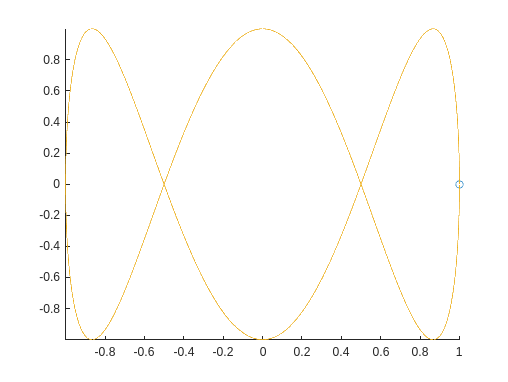

t = [0:0.001:2*pi];
x2 = cos(t);
y2 = sin(3*t);
comet(x2,y2)

Este fue el más complejo. Quería hacer una curva que combinara dos tipos de movimientos: uno rápido y uno lento. Por eso usé dos partes:

- La parte `sin(t)` y `cos(t)` es rápida (alta frecuencia), hace que la figura tenga vueltas cerradas.

- La parte `cos(t/20)` y `sin(t/20)` es más lenta (frecuencia muy baja), y como está multiplicada por 1.75, tiene más amplitud.

Al sumarlas, se combinan esos movimientos: uno girando rápido, y otro que cambia lentamente. El resultado es como una especie de espiral o patrón de flor que se va desplazando o rotando.

Para poder ver bien cómo se forma todo ese patrón, extendí `t` desde 0 hasta 40π, porque una vuelta normal no alcanza para notar el efecto. Así se alcanzan a ver varias vueltas del movimiento lento. .

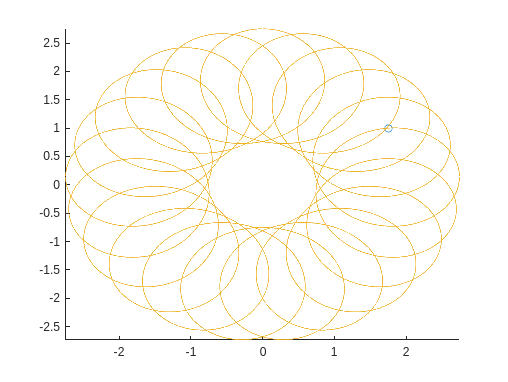

t = [0:0.001:40*pi];
x3 = 1*sin(t) + 1.75*cos(t/20) ;
y3 = 1*cos(t) + 1.75*sin(t/20) ;
comet(x3,y3)

#### 3. **Obtener** las siguientes trayectorias definidas a partir de curvas paramétricas

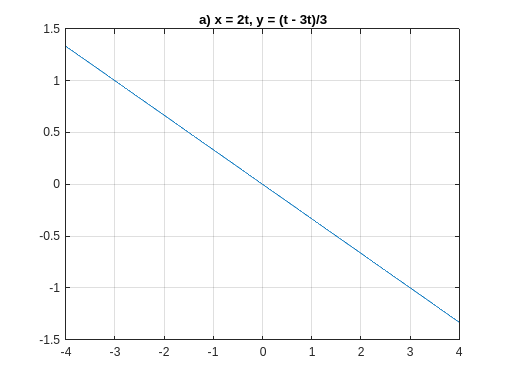

%% (a)  x = 2t,   y = (t - 3t)/3 = -2t/3,    t ∈ [-2, 2]
t = -2:0.01:2;
x4 = 2*t;
y4 = (t - 3*t)/3;  
figure
plot(x4, y4)
title('a) x = 2t, y = (t - 3t)/3')
grid on

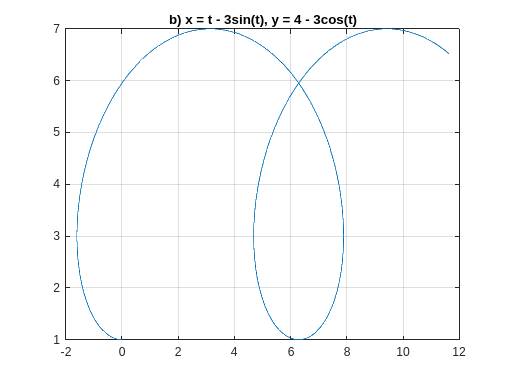


%% (b)  x = t - 3*sin(t),   y = 4 - 3*cos(t),   t ∈ [0, 10]
t = 0:0.01:10;
x5 = t - 3*sin(t);
y5 = 4 - 3*cos(t);
figure
plot(x5, y5)
title('b) x = t - 3sin(t), y = 4 - 3cos(t)')
grid on

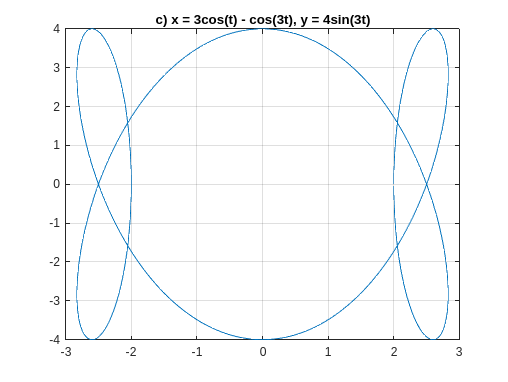


%% (c)  x = 3*cos(t) - cos(3t),   y = 4*sin(3t),   t ∈ [0, 2π]
t = 0:0.01:2*pi;
x6 = 3*cos(t) - cos(3*t);
y6 = 4*sin(3*t);
figure
plot(x6, y6)
title('c) x = 3cos(t) - cos(3t), y = 4sin(3t)')
grid on

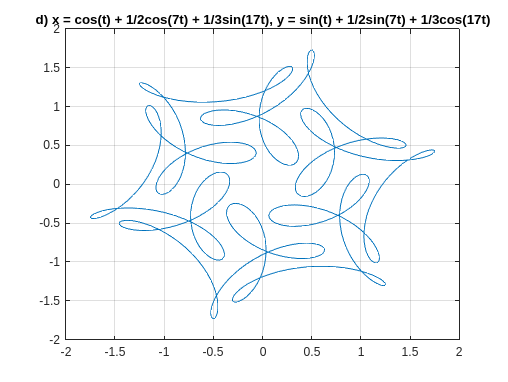


%% (d)  x = cos(t) + 1/2cos(7t) + 1/3sin(17t)
%       y = sin(t) + 1/2sin(7t) + 1/3cos(17t)
t = 0:0.01:2*pi;
x7 = cos(t) + (1/2)*cos(7*t) + (1/3)*sin(17*t);
y7 = sin(t) + (1/2)*sin(7*t) + (1/3)*cos(17*t);
figure
plot(x7, y7)
title('d) x = cos(t) + 1/2cos(7t) + 1/3sin(17t), y = sin(t) + 1/2sin(7t) + 1/3cos(17t)')
grid on

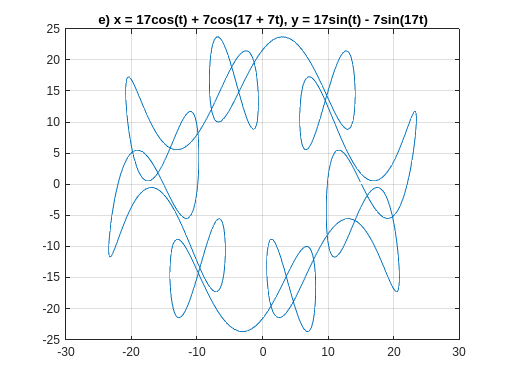


%% (e)  x = 17cos(t) + 7cos(17 + 7t),   y = 17sin(t) - 7sin(17t)
t = 0:0.01:2*pi;
x8 = 17*cos(t) + 7*cos(17 + 7*t);
y8 = 17*sin(t) - 7*sin(17*t);
figure
plot(x8, y8)
title('e) x = 17cos(t) + 7cos(17 + 7t), y = 17sin(t) - 7sin(17t)')
grid on

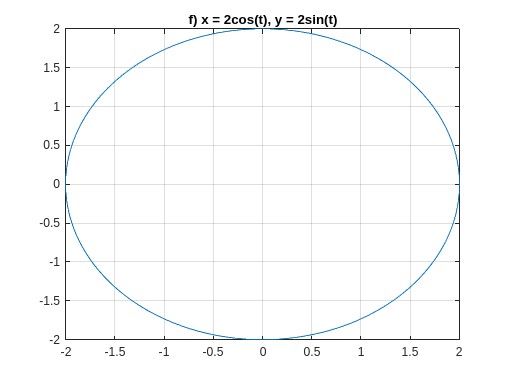


%% (f)  x = 2cos(t),  y = 2sin(t),  t ∈ [0, 14π]
t = 0:0.01:(14*pi);
x9 = 2*cos(t);
y9 = 2*sin(t);
figure
plot(x9, y9)
title('f) x = 2cos(t), y = 2sin(t)')
grid on

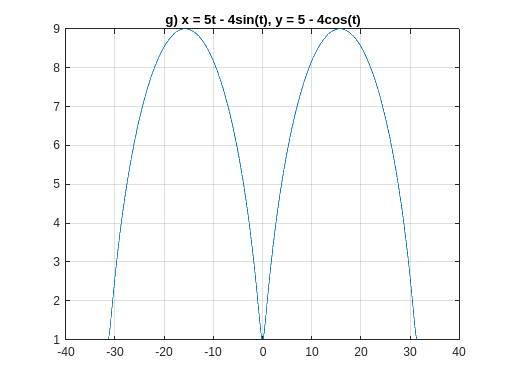


%% (g)  x = 5t - 4sin(t),   y = 5 - 4cos(t),   t ∈ [-2π, 2π]
t = -2*pi:0.01:2*pi;
x10 = 5*t - 4*sin(t);
y10 = 5 - 4*cos(t);
figure
plot(x10, y10)
title('g) x = 5t - 4sin(t), y = 5 - 4cos(t)')
grid on

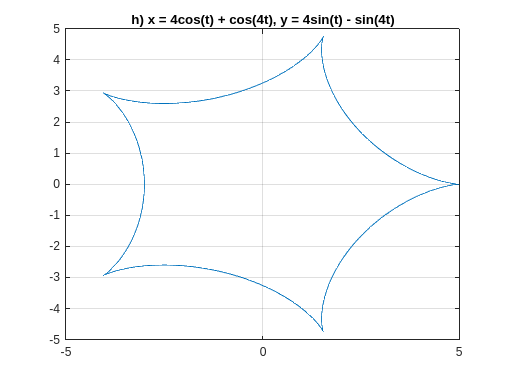


%% (h)  x = 4cos(t) + cos(4t),   y = 4sin(t) - sin(4t),   t ∈ [0, 2π]
t = 0:0.01:2*pi;
x11 = 4*cos(t) + cos(4*t);
y11 = 4*sin(t) - sin(4*t);
figure
plot(x11, y11)
title('h) x = 4cos(t) + cos(4t), y = 4sin(t) - sin(4t)')
grid on

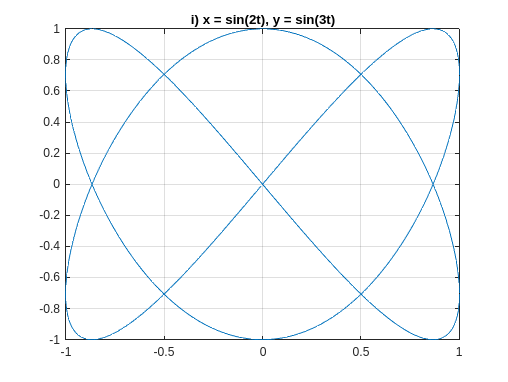


%% (i)  x = sin(2t),   y = sin(3t),   t ∈ [0, 2π]
t = 0:0.01:2*pi;
x12 = sin(2*t);
y12 = sin(3*t);
figure
plot(x12, y12)
title('i) x = sin(2t), y = sin(3t)')
grid on

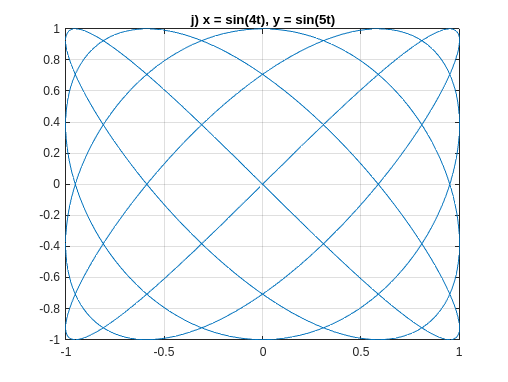


%% (j)  x = sin(4t),   y = sin(5t),   t ∈ [0, 2π]
t = 0:0.01:2*pi;
x13 = sin(4*t);
y13 = sin(5*t);
figure
plot(x13, y13)
title('j) x = sin(4t), y = sin(5t)')
grid on